clear all;
clc;
close all;

bag = ros2bagreader(["test_multiple5/"])

bag =   ros2bagreader with properties:

           FilePath: '/home/robotics/ur3_ros2/matlab/test_multiple5/test_multiple5_0.db3'
          StartTime: 1.6945e+09
            EndTime: 1.6945e+09
    AvailableTopics: [1×3 table]
        MessageList: [571261×3 table]
        NumMessages: 571261


% bag_force_z = select(bag,"Topic","/force_z");
% bag_position_desired = select(bag,"Topic","/position_desired");
% bag_position_real = select(bag,"Topic","/position_real");
% bag_surface = select(bag,"Topic","/surface");
bag_data = select(bag,"Topic","/data_control");
bag_data2 = select(bag,"Topic","/data_estimation");

bag_ft2 = select(bag,"Topic","/force_torque_sensor_broadcaster/wrench");
bag_ft = select(bag,"Topic","/bus0/ft_sensor0/ft_sensor_readings/wrench");
% bag_time = select(bag,"Topic","/clock");

% mes_force_z = readMessages(bag_force_z);
% mes_position_desired = readMessages(bag_position_desired);
% mes_position_real = readMessages(bag_position_real);
% mes_surface = readMessages(bag_surface);
mes_data = readMessages(bag_data);
mes_data2 = readMessages(bag_data2);
mes_ft = readMessages(bag_ft);
mes_ft2 = readMessages(bag_ft2);
% mes_time = readMessages(bag_time);
n_mess = bag_data.NumMessages;
% n_v = bag_position_desired.NumMessages;
% n_f = bag_position_real.NumMessages;
n_ft = bag_ft.NumMessages;
n_ft2 = bag_ft2.NumMessages;
%st = min([n_u,n_v,n_f])

sim_time = zeros(n_mess,1);
for i = 1:n_mess
    sim_time(i) =  mes_data{i, 1}.data(1);  
end
initial_time = sim_time(1);
sim_time(:) = sim_time(:)-initial_time;
dT = sim_time(2)

dT = 0.0020


force_z = zeros(n_mess,1);
for i = 1:n_mess
    force_z(i) =  mes_data{i, 1}.data(6);  
end

position_desired = zeros(n_mess,1);
for i = 1:n_mess
    position_desired(i) =  mes_data{i, 1}.data(4);
end

position_real = zeros(n_mess,1);
for i = 1:n_mess
    position_real(i) =  mes_data{i, 1}.data(3);  
end

velocity_z = zeros(n_mess,1);
for i = 1:n_mess
    velocity_z(i) =  mes_data{i, 1}.data(5);  
end

n_palp = zeros(n_mess,1);
for i = 1:n_mess
    n_palp(i) =  mes_data{i, 1}.data(7);  
end

max(n_palp)

ans = 230

for i=1:max(n_palp)+1
    surface_high(i) = mes_data{find(n_palp==i-1,1),1}.data(2);
    x_pos(i) = mes_data{find(n_palp==i-1,1),1}.data(8);
    y_pos(i) = mes_data{find(n_palp==i-1,1),1}.data(9);
end
xv = min(x_pos):0.0001:max(x_pos)

xv =    -0.1587   -0.1586   -0.1585   -0.1584   -0.1583   -0.1582   -0.1581   -0.1580   -0.1579   -0.1578   -0.1577   -0.1576   -0.1575   -0.1574   -0.1573   -0.1572   -0.1571   -0.1570   -0.1569   -0.1568   -0.1567   -0.1566   -0.1565   -0.1564   -0.1563   -0.1562   -0.1561   -0.1560   -0.1559   -0.1558   -0.1557   -0.1556   -0.1555   -0.1554   -0.1553   -0.1552   -0.1551   -0.1550   -0.1549   -0.1548   -0.1547   -0.1546   -0.1545   -0.1544   -0.1543   -0.1542   -0.1541   -0.1540   -0.1539   -0.1538


yv = min(y_pos):0.0001:max(y_pos)

yv =    -0.4145   -0.4144   -0.4143   -0.4142   -0.4141   -0.4140   -0.4139   -0.4138   -0.4137   -0.4136   -0.4135   -0.4134   -0.4133   -0.4132   -0.4131   -0.4130   -0.4129   -0.4128   -0.4127   -0.4126   -0.4125   -0.4124   -0.4123   -0.4122   -0.4121   -0.4120   -0.4119   -0.4118   -0.4117   -0.4116   -0.4115   -0.4114   -0.4113   -0.4112   -0.4111   -0.4110   -0.4109   -0.4108   -0.4107   -0.4106   -0.4105   -0.4104   -0.4103   -0.4102   -0.4101   -0.4100   -0.4099   -0.4098   -0.4097   -0.4096


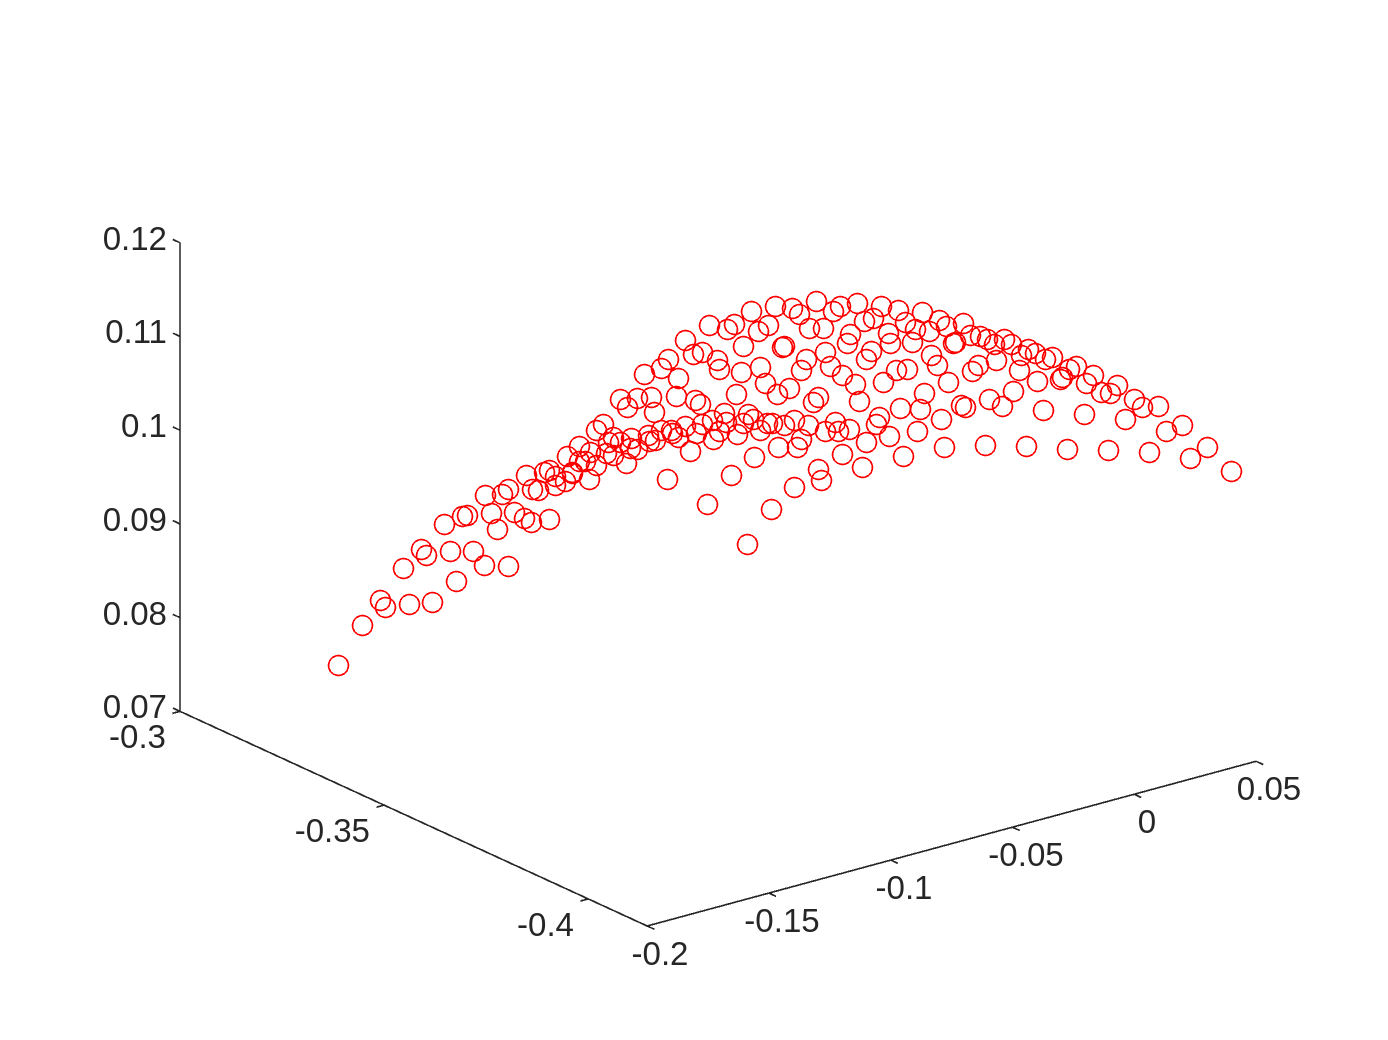

[Xv,Yv] = meshgrid(xv,yv);
Zv = griddata(x_pos,y_pos,surface_high,Xv,Yv);
plot3(x_pos,y_pos,surface_high,"ro")
hold on
% surf(Xv,Yv,Zv)
hold off 

% gprMH = fitrgp(pos,surface_high')%,"FitMethod","exact","KernelFunction","squaredexponential","KernelParameters",phi);
% [hPred,hVar] = predict(gprMH,[Xv(:),Yv(:)]);
% hPred = reshape(hPred,length(Yv(:,1)),length(Xv));
% surf(Xv,Yv,hPred)

n =1.35

n = 1.3500

lsqr_method = zeros(3,max(n_palp)+1);
for i=1:max(n_palp)+1
    data_position = find(n_palp==i-1);
    p = 0.0025+surface_high(i) - position_real(data_position);
    pp = -velocity_z(data_position);
    ppp = zeros(length(data_position),1);
    ppp(1:length(data_position)-1) = diff(pp)/(dT);
    ppp(length(data_position))=ppp(length(data_position)-1);
    force_z_ext = force_z(data_position);
    lsqr_method(:,i) = real(lsqr([p.^(n),pp.*p.^(n),ppp],force_z_ext));
    
    % plot(lsqr_method(1) * abs(p).^(n) + lsqr_method(2)*pp.* abs(p).^(n) + lsqr_method(3) * ppp)
    % hold on 
    % plot(force_z_ext)
    % hold off 
end

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.017.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.024.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.02.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.018.
lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.013.
lsqr stopped at iteration 3 without 

lsqr_method

lsqr_method = 1.0e+05 *

    0.0289    0.0287    0.0298    0.0299    0.0290    0.0264    0.0250    0.0242    0.0228    0.0212    0.0219    0.0318    0.0327    0.0338    0.0346    0.0335    0.0323    0.0315    0.0299    0.0273    0.0256    0.0251    0.0359    0.0372    0.0384    0.0386    0.0383    0.0381    0.0381    0.0371    0.0352    0.0323    0.0301    0.0408    0.0431    0.0440    0.0450    0.0447    0.0453    0.0463    0.0445    0.0411    0.0374    0.0351    0.0502    0.0550    0.0585    0.0612    0.0603    0.0584
    0.1993    0.2001    0.2034    0.2061    0.1852    0.1946    0.1911    0.1855    0.1851    0.1707    0.1800    0.2413    0.2576    0.2610    0.2755    0.2707    0.2876    0.3099    0.3007    0.2647    0.2680    0.2510    0.3083    0.3068    0.3131    0.3334    0.3499    0.3687    0.3898    0.3830    0.3683    0.3528    0.3366    0.3501    0.3812    0.3978    0.4282    0.4304    0.4506    0.4767    0.4659    0.4357    0.4060    0.3764    0.4814    0.5673    0.6533    

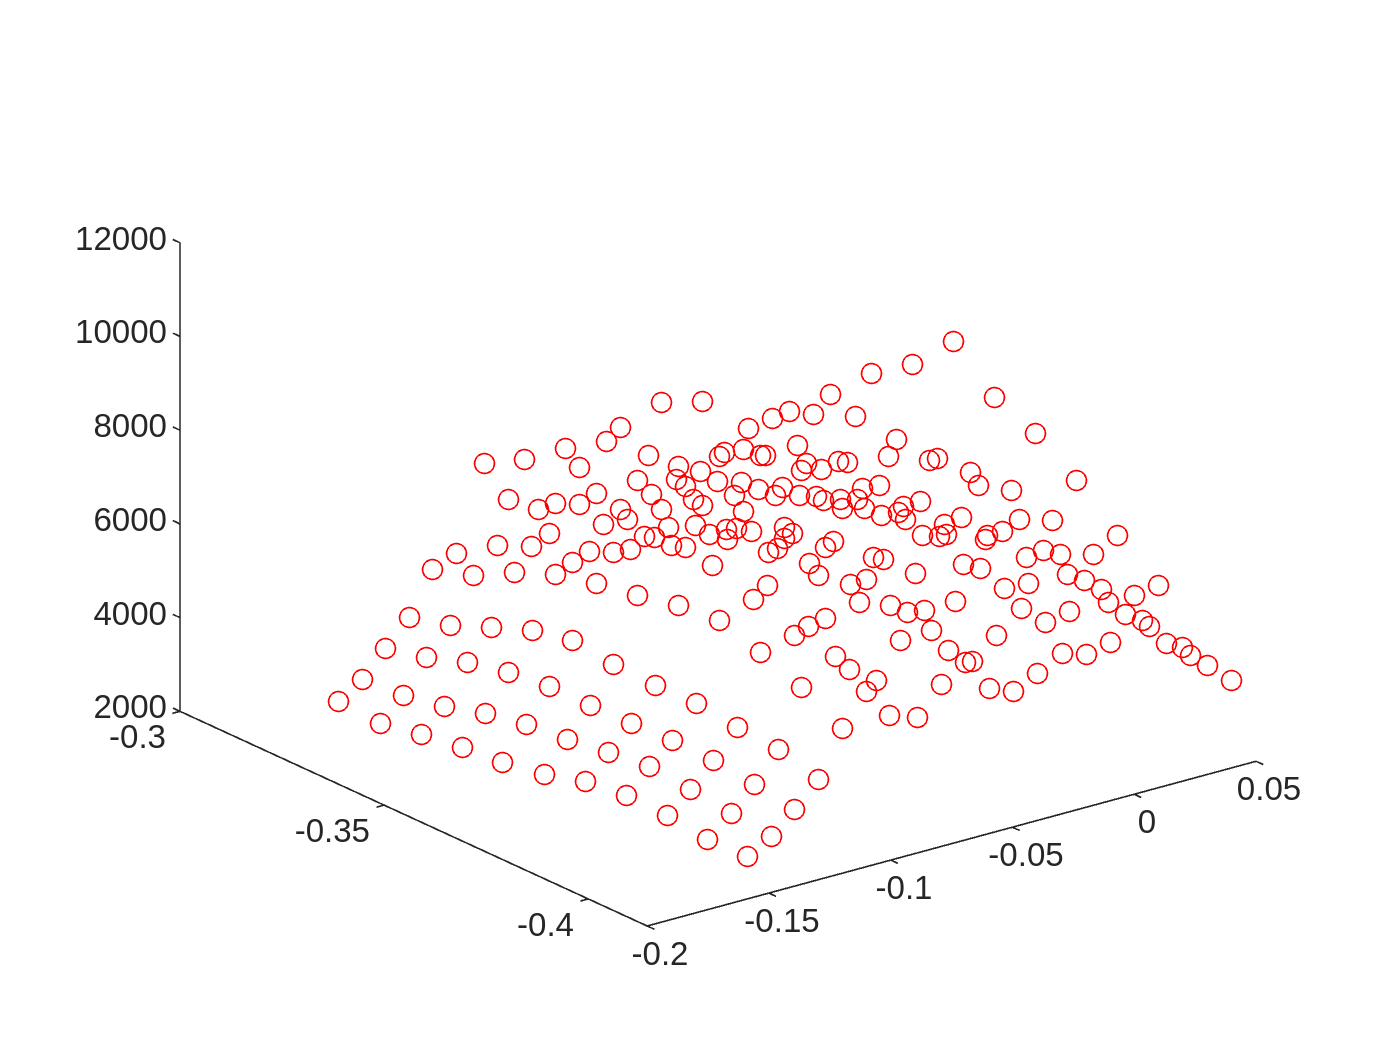

Zk = griddata(x_pos,y_pos,lsqr_method(1,:),Xv,Yv);
plot3(x_pos,y_pos,lsqr_method(1,:),"ro")


plot3(x_pos,y_pos,surface_high,"ro")
hold on

surf(Xv,Yv,Zv,Zk)

Index in position 1 is invalid. Array indices must be positive integers or logical values.

'surf' appears to be both a function and a variable. If this is unintentional, use 'clear surf' to remove the variable 'surf' from the workspace.

hold off

pos = [x_pos',y_pos'];
phi = [0.02,1];
gprM = fitrgp(pos,lsqr_method(1,:)')%,"FitMethod","exact","KernelFunction","squaredexponential","KernelParameters",phi);
[kPred,zVar] = predict(gprM,[Xv(:),Yv(:)]);
kPred = reshape(kPred,length(Yv(:,1)),length(Xv));
zVar = reshape(zVar,length(Yv(:,1)),length(Xv));

plot(kPred(2,:))
hold on
plot(zVar(2,:))
hold off 


gprMD = fitrgp(pos,lsqr_method(2,:)')%,"FitMethod","exact","KernelFunction","squaredexponential","KernelParameters",phi);
[dPred,dVar] = predict(gprMD,[Xv(:),Yv(:)]);
dPred = reshape(dPred,length(Yv(:,1)),length(Xv));
dVar = reshape(dVar,length(Yv(:,1)),length(Xv));

plot(dPred(2,:))
hold on
plot(dVar(2,:))
hold off 


%plot3(x_pos,y_pos,surface_high,"ro")
%hold on
surf(Xv,Yv,Zv,kPred)
%hold off

%lsqr_method2 = real(lsqr([p(20000:30000),-velocity_z(20000:30000),ppp(20000:30000)],force_z(20037:30037)))

% Get the coefficients 'a' and 'b' from the model
%stiffness = mdl.Coefficients.Estimate(1); % Coefficient for 'x'
%damping = mdl.Coefficients.Estimate(2); % Coefficient for 'y'
%mass = mdl.Coefficients.Estimate(3); % Coefficient for 'y'

%plot(lsqr_method(1) * abs(p).^(1.3) - lsqr_method(2) * velocity_z .*abs(p).^(1.3) + lsqr_method(3) * ppp)
% plot(sim_time,lsqr_method(1) * abs(p).^(1.35) + lsqr_method(2)*pp.* abs(p).^(1.35 ) + lsqr_method(3) * ppp)
% hold on 
% plot(sim_time,force_z)
% hold off 
% %xlim([10000,20000])
% legend(["est","ft_s"])

g = gridfit(x_pos,y_pos,surface_high,xv,yv);
figure
colormap(hot(256));
surf(xv,yv,g,kPred);
shading interp

% writematrix(Xv(1,:)','data_body/x.txt')
% writematrix(Yv(:,1),'data_body/y.txt')
% writematrix(g(:),'data_body/z.txt')
% writematrix(kPred(:),'data_body/stiffness.txt')
% writematrix(dPred(:),'data_body/damping.txt')
% for i= 1000:1000:30000
%     [x,flag,relres,iter,resvec,lsvec] = lsqr([p(1:i).^(n),-velocity_z(1:i).*p(1:i).^(n),ppp(1:i)],force_z(1:i));
%     resi(i/1000)=relres;
% end
% plot(resi)